# DONT RUN IF YOU DONT WANT TO ERASE DATE

# THIS WILL OVERWRITE THE PREVIOUS TRAINING DATA

clc
clear all
close all
rng(0)
save_buffer = false;

To know the absolute limits on $i_{\epsilon }$ (the independently linear currents), it is possible to sample points of $i_B$ and transform it back to $i_{\epsilon }$

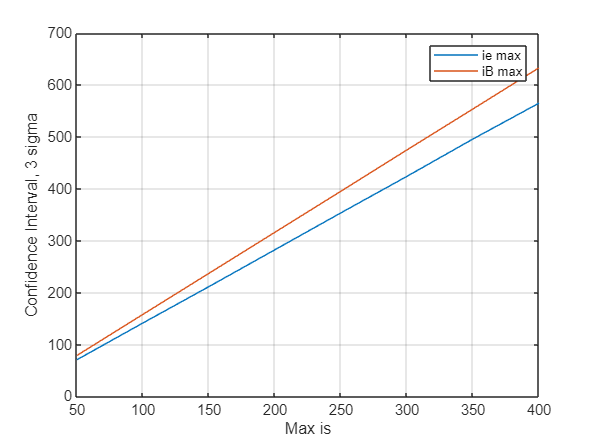

A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
N = null(A, 'rational');
iss = [50, 100, 150, 250, 300, 350, 400];
n_experiments = length(iss);
x = zeros(n_experiments, 1);
y1 = zeros(n_experiments, 1);
y2 = zeros(n_experiments, 1);

for idx = 1:n_experiments
    n_samples = 100000;
    % Arcsine distribution for cluster currents
    is = sin(2*pi*rand(9, n_samples))*iss(idx);

    % Calculation of external currents
    ixy = A*is;
    % Calculation of basic currents
    iB = pinv(A)*ixy;
    % Confidence interval of basic currents
    iB_max = std(iB(:))*3;
    % Calculation of circulating currents
    iz = is - iB;
    
    % Calculation of linearly independent currents
    ie = pinv(N)*iz;
    % Confidence interval of linearly independent currents
    ie_max = std(ie(:))*3;

    x(idx) = iss(idx);
    y1(idx) = ie_max;
    y2(idx) = iB_max;
end
figure
plot(x, y1)
hold on
plot(x, y2)
xlabel("Max is")
ylabel("Confidence Interval, 3 sigma")
legend('ie max', 'iB max')
grid on


X = [ones(n_experiments, 1), x];
beta = pinv(X'*X)*X'*y1

beta =     0.0194
    1.4139


ie_max = beta'*[1; 250]

ie_max = 353.4882


X = [ones(n_experiments, 1), x];
beta = pinv(X'*X)*X'*y2

beta =    -0.1350
    1.5827


iB_max = beta'*[1; 250]

iB_max = 395.5300


ie_max = y1(iss==250)

ie_max = 353.6856

iB_max = y2(iss==250)

iB_max = 395.3491


% En el caso de las corrientes linealmente independientes, la maxima es
% aproximadamente ie_max=1.42*Is_max. Por esto se normalizará la salida de
% la red correspondiente al vector ie, por 1.5*Is_max.
% Mientras que en el caso de las corrientes basicas, la maxima es
% aproximadamente iB_max=1.58*Is_max. Por esto se normalizará la entrada de
% la red correspondiente al vector iB, por 2*Is_max.

# M3C Sample Generator

## Parameters

Simulation and control steps

%% Simulation
Ts = 2e-5;	                 % Sample time
%% ICB + LFOM
Tl = 1e-4;                   % Sample time
lmax = 10;                   % BCD solver max iterations
% BCD solver prediction horizon
Np = 1;
tp = linspace(0, Np*Tl, Np);

Converter model

% M3C incidence matrix
A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m = size(A, 2);
N = null(A, 'rational');
pinvN = pinv(N);
n = size(N, 2);          % Number of circulating currents
C = 20e-3;			     % Average cluster capacitance
L = 200e-4;              % Branch inductance
R = 0.001;			     % Branch resistance

Current discrete model

% Fundamental step size
Ad_s = expm(-Ts*R/L*eye(m));
Bd_s = (-R/L*eye(m))\(Ad_s-eye(m))*(-eye(m)/L);

% Energy and current control step size
Ad_l = expm(-Tl*R/L*eye(m));
Bd_l = (-R/L*eye(m))\(Ad_l-eye(m))*(-eye(m)/L);

Let's assume we know exactly the future grid voltage

% Input
Ax = 7000;
fx0 = 50;
wx0 = 2*pi*fx0;
% Output
Ay = 5000;
fy0 = 50;
wy0 = 2*pi*fy0;

Also, it is possible to assume symmetrical three phase currents with same frequency and phase as the voltages

(At least for the reference currents)

Iy = 150;
Ix = Ay/Ax*Iy

Ix = 107.1429

## Simulation

Diagonal matrix

D = @(vector) diag(vector);

Limit values

Vxy_max = Ax+Ay;      % Branch voltage
Von_max = Vxy_max/2   % Common mode voltage

Von_max = 6000

Is_max = 250          % Cluster current

Is_max = 250

Ix_max = 200;         % Input current
Iy_max = Ax/Ay*Ix_max % Output current

Iy_max = 280

Constant references

%% Cluster capacitor voltage reference
vc_ref = 1.5*Vxy_max;
%% Cluster capacitor energy reference
Ec_ref = vc_ref^2*C/(4*2);

- ICB + LFOM

% Parameters
lambda_z = 2*Np;
lambda_o = 0.1*Np;
% Initialization
iAi = false(size([ones(m*Np, 1); -ones(m*Np, 1)]));
iAv = false(size([ones(Np, 1); -ones(Np, 1)]));

- Cluster current control

% Parameters
lambda = 0.00005;
% Initialization
iA = false(size([ones(m*Np, 1); -ones(m*Np, 1)]));

## Generate control data

Initialize buffer

env = classM3C

env =   classM3C with properties:

                    Tf: 0.5000
                    Ts: 2.0000e-05
                    Ti: 1.0000e-04
                Ti_idx: 5
                    Tl: 1.0000e-04
                Tl_idx: 5
                    Ax: 7000
                   fxi: 50
                   wx0: 314.1593
                    Ay: 5000
                   fyi: 30
                   wy0: 188.4956
                     A: [6×9 double]
                 pinvA: [9×6 double]
                     m: 9
                     N: [9×4 double]
                 pinvN: [4×9 double]
                     C: 0.0200
                     L: 0.0200
                     R: 1.0000e-03
               Tabc_ab: [2×3 double]
               Tab_abc: [3×2 double]
      Tabc_dq_function: @(g)(2/3)*[cos(g),cos(g-2*pi/3),cos(g+2*pi/3);-sin(g),-sin(g-2*pi/3),-sin(g+2*pi/3)]
               Vxy_max: 12000
               Von_max: 6000
                Is

% InitialObservation = reset(env)

obsInfo = env.getObservationInfo

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "ICB+LFOM Inputs"
    Description: "Ec (9), vB (9), iB (9)"
      Dimension: [27 1]
       DataType: "double"

actInfo = env.getActionInfo

actInfo =   rlNumericSpec with properties:

     LowerLimit: [5×1 double]
     UpperLimit: [5×1 double]
           Name: "ICB+LFOM Outputs"
    Description: "ie (4), von (1)"
      Dimension: [5 1]
       DataType: "double"

Nsamples = 1000;

buffer = rlReplayMemory(obsInfo, actInfo, Nsamples)

buffer =   rlReplayMemory with properties:

    MaxLength: 1000
       Length: 0

Initialization randomness

% 2 or 3 sigma rule for confidence interval of a gaussian random variable
confidence_interval = 0.01;                   % "Max value"
stdev = confidence_interval/3                 % 2 or 3 sigma rule

stdev = 0.0033

random_variable = randn(1, 100000) * stdev;
mask = abs(random_variable) < confidence_interval;
sum(mask)/length(random_variable)

ans = 0.9972

std(random_variable)

ans = 0.0033

% Energy: In the M3C simulation, with fx=fy=50Hz and Idy_ref=150, with one
% step ICB+LFOM, the max energy deviation is approx 2000J. With
% Ec_ref=810000, maximum deviation in percentage is 2000/810000=0.0026
stdev_Ec = 0.005/3;
% Ec = Ec_ref * (1 + randn(m, 1)*stdev_Ec)

% Time (Percentage of the period) between [0, 1]
% pT = rand(); 

% Currents: Assuming max 10% "error in the control"

% Basic current
stdev_iB = 0.1/3;
% iB = iB_ref .* (1 + randn(m, 1)*stdev_iB);

% Circulating current
stdev_iz = 0.1/3;
% iz = iz_ref .* (1 + randn(m, 1)*stdev_iz);

One Step Simulation

tic
for t = 1:Nsamples
% Initialize actual experience
experience = struct("Observation", zeros(obsInfo.Dimension), "Action", zeros(actInfo.Dimension), "Reward", 0, "NextObservation", zeros(obsInfo.Dimension), "IsDone", 0);
experience.IsDone = 0;

% Initial capacitor energy
Ec = Ec_ref * (1 + randn(m, 1)*stdev_Ec);
% Actual clusters energies mean
Ec_mean = mean(Ec);
if Ec_mean == 0
    Ec_mean = Ec_mean + 1e-3;
end

% Initial input/output angle
pT = rand();
gx = 2*pi*pT*wx0/wy0;
gy = 2*pi*pT;

% Initial input/output voltages
vxa = Ax*cos(gx);
vxb = Ax*cos(gx-2*pi/3);
vxc = Ax*cos(gx+2*pi/3);
vyr = Ay*cos(gy);
vys = Ay*cos(gy-2*pi/3);
vyt = Ay*cos(gy+2*pi/3);
vxy = [vxa; vxb; vxc; vyr; vys; vyt];

% Initial branch voltages
vB = A'*vxy;

% Initial input/output currents references
ixa_ref = Ix*cos(gx);
ixb_ref = Ix*cos(gx-2*pi/3);
ixc_ref = Ix*cos(gx+2*pi/3);
iyr_ref = Iy*cos(gy);
iys_ref = Iy*cos(gy-2*pi/3);
iyt_ref = Iy*cos(gy+2*pi/3);
ixy_ref = [ixa_ref; ixb_ref; ixc_ref; iyr_ref; iys_ref; iyt_ref];

% Initial basic currents references
iB_ref = pinvA*ixy_ref;

% Initial basic currents
iB = iB_ref .* (1 + randn(m, 1)*stdev_iB);

%%%% Save Input Data (Observations)
experience.Observation = {[Ec; vB; iB]};
%%%%

%%% ICB+LFOM control
% One step
% Active Set + Block Coordinate Descent
von_temp = 0;
for l = 1:lmax
    % Circulating currents subproblem
    % Initialization
    vs_temp = vB + von_temp;
    % Formulation
    HE_ie = 2*Tl^2*D(vs_temp)^2;
    fE_ie = 2*Tl*D(vs_temp)*(Ec - mean(Ec) + Tl*D(vs_temp)*iB);
    Hi_ie = eye(m);
    fi_ie = zeros(m, 1);
    H_ie = HE_ie + lambda_z*Hi_ie;
    f_ie = fE_ie + lambda_z*fi_ie;
    H_ie = N'*H_ie*N;
    f_ie = N'*f_ie;
    H_ie = (H_ie + H_ie')/2;
    % Solve
    ub = Is_max*ones(m, 1)-iB;
    lb = -Is_max*ones(m, 1)-iB;
    options = mpcActiveSetOptions;
    options.MaxIterations = 20;
    options.ConstraintTolerance = 1e-3;
    [ie_ref_temp, exitflag, iAi, muz] = mpcActiveSetSolver(H_ie, f_ie, [N; -N], [ub; -lb], zeros(0, n), zeros(0, 1), iAi, options);
    iz_ref_temp = N*ie_ref_temp;
    
    % Common mode voltage subproblem
    % Initialization
    is_temp = iB + iz_ref_temp;
    % Formulation
    HE_von = 2*Tl^2*D(is_temp)^2;
    fE_von = 2*Tl*D(is_temp)*(Ec - mean(Ec) + Tl*D(is_temp)*vB);
    Hv_von = eye(m);
    fv_von = zeros(m, 1);
    H_von = HE_von + lambda_o*Hv_von;
    f_von = fE_von + lambda_o*fv_von;
    H_von = ones(1, m)*H_von*ones(m, 1);
    f_von = ones(1, m)*f_von;
    H_von = (H_von + H_von')/2;
    % Solve
    ub = Von_max;
    lb = -ub;
    options = mpcActiveSetOptions;
    options.MaxIterations = 10;
    options.ConstraintTolerance = 1e-3;
    [von_temp, exitflag, iAv, muv] = mpcActiveSetSolver(H_von, f_von, [1; -1], [ub; -lb], zeros(0, 1), zeros(0, 1), iAv, options);
end
ie_ref = ie_ref_temp;
iz_ref = iz_ref_temp;
von = von_temp;
is_ref = iB_ref + iz_ref;

%%%% Save Output Data (Actions)
experience.Action = {[ie_ref; von]};
%%%%

iz = iz_ref .* (1 + randn(m, 1)*stdev_iz);
is = iB + iz;

%%% CC control
Hi =  2*(Bd_l')*Bd_l;
fi = 2*Bd_l'*(Ad_l*is-is_ref);
Hv = eye(m);
fv = zeros(m, 1);
H = Hi + lambda*Hv;
f = fi + lambda*fv;
H = (H+H')/2;
options = mpcActiveSetOptions;
options.MaxIterations = 100;
options.ConstraintTolerance = 1.0e-4;
p = -(vB + von);
ub = vc_ref*ones(m, 1) + p;
lb = -vc_ref*ones(m, 1) + p;
[Z, exitflag, iA, mu] = mpcActiveSetSolver(H, f, [eye(m); -eye(m)], [ub; -lb], zeros(0, m), zeros(0, 1), iA, options);
vs = Z-p;

%%%% Environement transition with fundamental step (Ts) until next control step (Tl)
for tt = 1:env.Tl_idx
    % Next input/output angle
    gx = gx + wx0*Ts;
    gy = gy + wy0*Ts;

    % Next input/output voltage
    vxa = Ax*cos(gx);
    vxb = Ax*cos(gx-2*pi/3);
    vxc = Ax*cos(gx+2*pi/3);
    vyr = Ay*cos(gy);
    vys = Ay*cos(gy-2*pi/3);
    vyt = Ay*cos(gy+2*pi/3);
    vxy = [vxa; vxb; vxc; vyr; vys; vyt];
    
    % Next input/output voltage
    vB = A'*vxy;

    % Next cluster currents
    is = Ad_s*is + Bd_s*(vs - vB - von);
    
    % Next cluster energies
    Ec = Ec + Ts*vs.*is;
end

ixy = A*is;
iB = pinvA*ixy;

%%% Save Next Observation 
experience.NextObservation = {[Ec; vB; iB]};

%%%% Save Reward
JE = norm(1 - Ec / Ec_mean)^2;
Jz = norm(iz_ref/Is_max)^2 * (Is_max/Ec_mean)^2;
Jo = norm(von/Von_max)^2 * (Von_max/Ec_mean)^2;
J = JE + lambda_z*Jz + lambda_o*Jo;
experience.Reward = -J;

%%%% Add Experience
validateExperience(buffer, experience)
append(buffer, experience)
end

toc

Elapsed time is 9.804690 seconds.


if save_buffer
    save('Simulations\data\bufferBC.mat', "buffer")
end

Outputs

- Input/output size for raw data: Ninputs, Noutputs

- Data for FFNN: X, Y, X_train, Y_train, X_val, Y_val

- Data for RNN: Xseq, Yseq, Xseq_train, Yseq_train, Xseq_val, Yseq_val

- Normalization limits: Xmin, Xmax, Ymin, Ymax

## Normalization parameters

Ax

Ax = 7000

Ay

Ay = 5000

Is_max

Is_max = 250

C

C = 0.0200

Von_max

Von_max = 6000


E = (C/2/4)*(1.5*(Ax+Ay))^2 *1.1  % Capacitor energy

E = 8.9100e+05

VB = (Ax+Ay) *1.1 % Branch voltages

VB = 19800

IB = 2*Is_max % Basic currents

IB = 500

IE = 1.5*Is_max % Linear independet currents

IE = 375


Xmax = [E*ones(9, 1); VB*ones(9, 1); IB*ones(9, 1)];
Ymax = [IE*ones(4, 1); Von_max];

# Load data from trajectories

% Ec_NN
% Ec_ref_NN
% Vxy_NN
% V_NN
% Ixy_NN
% IB_NN
% Ixy_ref_NN
% IB_ref_NN
% Vs_NN
% Is_NN
% Ie_NN
% Von_NN
% Ec_pred_NN

load('simulation_data.mat', 'simulation_data');
runs = fieldnames(simulation_data)

runs = 6×1 cell array
    {'run1'}
    {'run2'}
    {'run3'}
    {'run4'}
    {'run5'}
    {'run6'}

fields = fieldnames(simulation_data.(runs{1}))

fields = 13×1 cell array
    {'Ec'     }
    {'Ec_ref' }
    {'vxy'    }
    {'vB'     }
    {'ixy'    }
    {'iB'     }
    {'ixy_ref'}
    {'iB_ref' }
    {'vs'     }
    {'is'     }
    {'ie'     }
    {'von'    }
    {'Ec_pred'}


concat_runs = struct();

for j = 1:numel(fields)
    all_series = [];

    for i = 1:numel(runs)
        current_series = simulation_data.(runs{i}).(fields{j});
        all_series = [all_series, current_series];
    end
    concatenated_data.(fields{j}) = all_series;
end

Ec_NN = concatenated_data.Ec;
Ec_ref_NN = concatenated_data.Ec_ref;
Vxy_NN = concatenated_data.vxy;
VB_NN = concatenated_data.vB;
Ixy_NN = concatenated_data.ixy;
IB_NN = concatenated_data.iB;
Ixy_ref_NN = concatenated_data.ixy_ref;
IB_ref_NN = concatenated_data.iB_ref;
Vs_NN = concatenated_data.vs;
Is_NN = concatenated_data.is;
Ie_NN = concatenated_data.ie;
Von_NN = concatenated_data.von;
Ec_pred_NN = concatenated_data.Ec_pred;

# Input/output selection

## Predict only control actions

Input

X = [Ec_NN; VB_NN; IB_NN];

Output

Y = [Ie_NN; Von_NN];

## Predict control actions + one step forward energy (PINN)

% X = X(:, 1:end-1);
% Y = [Ie_NN(:, 1:end-1); Von_NN(1:end-1); Ec_NN(:, 2:end)];

# Load data from random data generator

load('bufferBC.mat', 'buffer');
buffer_struct = buffer.allExperiences;
Nsamples = numel(buffer_struct);

Ninputs = env.getObservationInfo.Dimension(1);
Noutputs = env.getActionInfo.Dimension(1);

X = zeros(Ninputs, Nsamples);
Y = zeros(Noutputs, Nsamples);
for idx = 1:Nsamples
    X(:, idx) = buffer_struct(idx).Observation{:};
    Y(:, idx) = buffer_struct(idx).Action{:};
end

# Preprocessing

Input/output sizes

[Ninputs, Nsamples] = size(X)

Ninputs = 27

Nsamples = 100000

[Noutputs, Nsamples] = size(Y)

Noutputs = 5

Nsamples = 100000

Normalization

X = X ./ Xmax;
Y = Y ./ Ymax;

Transform to dlarray

dlX = dlarray(X, 'CB');
dlY = dlarray(Y, 'CB');

Training/validation split

cv = cvpartition(Nsamples, 'HoldOut', 0.2);
idx_tr = training(cv);
idx_val = test(cv);

X_tr = X(:, idx_tr);
Y_tr = Y(:, idx_tr);
X_val = X(:, idx_val);
Y_val = Y(:, idx_val);

dlX_tr = dlX(:, idx_tr);
dlY_tr = dlY(:, idx_tr);
dlX_val = dlX(:, idx_val);
dlY_val = dlY(:, idx_val);

# Exploratory data analysis

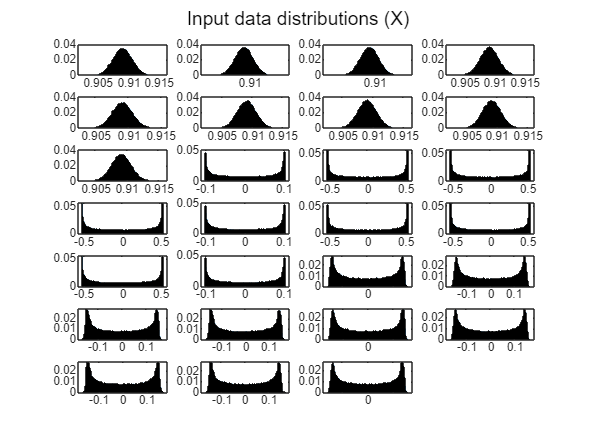

n_cols = 4;

figure
for idx = 1:Ninputs
    subplot(ceil(Ninputs / n_cols), n_cols, idx);
    if or(min(X(idx, :))<-1, max(X(idx, :))>1)
        histogram(X(idx, :), 100, 'Normalization', 'probability', 'FaceColor', 'red', 'EdgeColor', 'red');
    else
        histogram(X(idx, :), 100, 'Normalization', 'probability');
    end
    % title(['X', num2str(idx)]);
    % ylabel('Freq');
end
sgtitle('Input data distributions (X)')

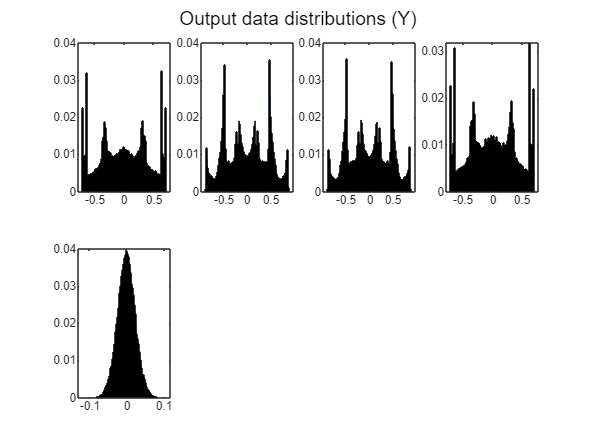


figure
for idx = 1:Noutputs
    subplot(ceil(Noutputs / n_cols), n_cols, idx)
    if or(min(Y(idx, :))<-1, max(Y(idx, :))>1)
        histogram(Y(idx, :), 100, 'Normalization', 'probability', 'FaceColor', 'red', 'EdgeColor', 'red')
    else
        histogram(Y(idx, :), 100, 'Normalization', 'probability')
    end
    % title(['Y', num2str(idx)])
    % ylabel('Freq')
end
sgtitle('Output data distributions (Y)')

# Sequencial data

% Nwindow = 10;
% 
% Nseq = Nsamples - Nwindow + 1;
% 
% Xseq = cell(Nseq, 1);
% Yseq = cell(Nseq, 1);
% 
% for i = 1:Nseq
%     Xseq{i} = X(:, i:(i + Nwindow - 1));
%     Yseq{i} = Y(:, i + Nwindow - 1);
% end
% 
% Xmat = zeros(Ninputs, Nwindow, Nseq);
% Ymat = zeros(Noutputs, Nseq);
% 
% for i = 1:Nseq
%     Xmat(:, :, i) = Xseq{i};
%     Ymat(:, i) = Yseq{i};
% end
% 
% dlXseq = dlarray(Xmat, 'CTB');
% dlYseq = dlarray(Ymat, 'CB');

Train/validation split

% cv = cvpartition(size(dlYseq, 2), 'HoldOut', 0.2);
% 
% idx_tr = training(cv);
% idx_val = test(cv);
% 
% dlXseq_tr = dlXseq(:, idx_tr, :);
% dlYseq_tr = dlYseq(:, idx_tr);
% dlXseq_val = dlXseq(:, idx_val, :);
% dlYseq_val = dlYseq(:, idx_val);

# Data quality inspection

Dimensionality reduction on state trajectories (PCA)

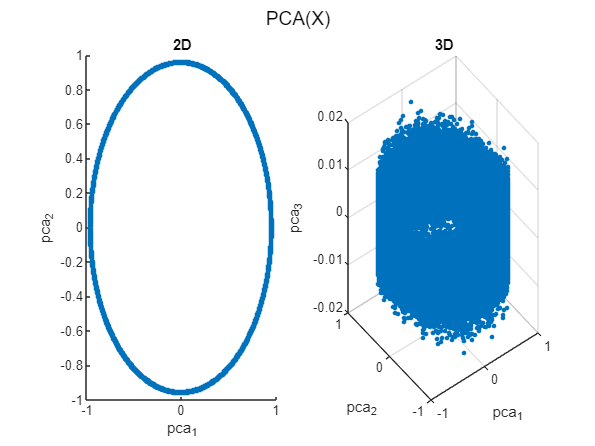

[coeff, score, latent] = pca(X');

figure
subplot(1, 2 ,1)
scatter(score(:, 1), score(:, 2), 10, 'filled');
title('2D');
xlabel('pca_1');
ylabel('pca_2');

subplot(1, 2, 2)
scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled');
title('3D');
xlabel('pca_1');
ylabel('pca_2');
zlabel('pca_3');

sgtitle('PCA(X)')

Dimensionality reduction on output data

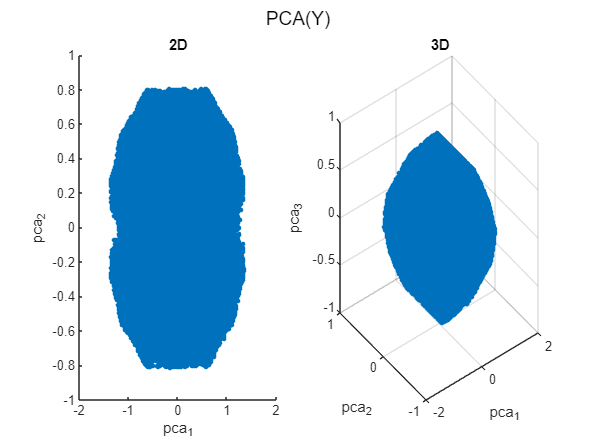

[coeff, score, latent] = pca(Y');

figure
subplot(1, 2, 1)
scatter(score(:, 1), score(:, 2), 10, 'filled');
title('2D');
xlabel('pca_1');
ylabel('pca_2');

subplot(1, 2, 2)
scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled');
title('3D');
xlabel('pca_1');
ylabel('pca_2');
zlabel('pca_3');

sgtitle('PCA(Y)')

% Reducir dimensionalidad con PCA
num_dims = 3; % Dimensiones para clustering
% [coeff, score, latent] = pca(X');
[coeff, score, latent] = pca(Y');
X_reduced = score(:, 1:num_dims); % Usar las primeras 'num_dims' componentes principales

% Clustering en el espacio reducido
n_clusters = 5; % Número de clusters
epsilon = 0.13;  % Radio máximo para DBSCAN
minPts = 5;     % Mínimo número de puntos para DBSCAN

% K-means clustering
[idx_kmeans, C_kmeans] = kmeans(X_reduced, n_clusters, 'Replicates', 10);

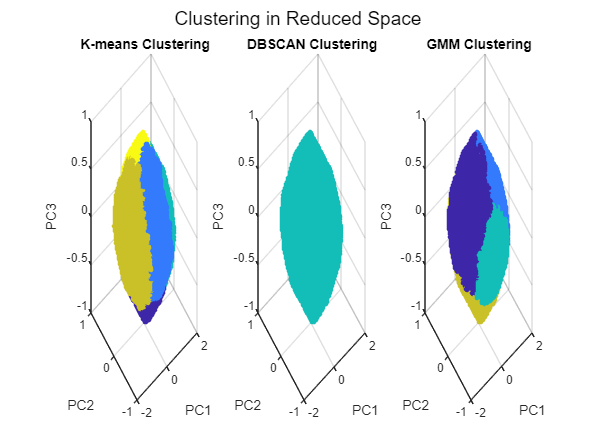


% DBSCAN clustering
idx_dbscan = dbscan(X_reduced, epsilon, minPts);

% GMM clustering
gmm = fitgmdist(X_reduced, n_clusters, 'RegularizationValue', 1e-5);
idx_gmm = cluster(gmm, X_reduced);

% Visualización de Clusters en el Espacio Reducido
figure

% subplot(3, 1, 1)
subplot(1, 3, 1)
scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_kmeans, 'filled');
title('K-means Clustering');
xlabel('PC1');
ylabel('PC2');
zlabel('PC3');

% subplot(3, 1, 2)
subplot(1, 3, 2)
scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_dbscan, 'filled');
title('DBSCAN Clustering');
xlabel('PC1');
ylabel('PC2');
zlabel('PC3');

% subplot(3, 1, 3)
subplot(1, 3, 3)
scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_gmm, 'filled');
title('GMM Clustering');
xlabel('PC1');
ylabel('PC2');
zlabel('PC3');

sgtitle('Clustering in Reduced Space');